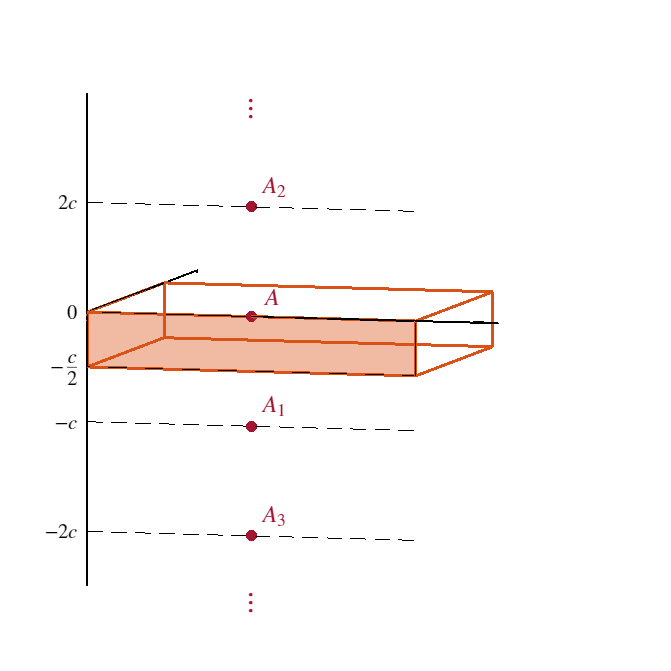

clear
clc

% To save in High Quality .svg :
% Open Figure Window > File > Export Setup
% Rendering Tab : Tick "Custom Renderer", select "Painters (vector format)"
% Select High DPI
% Press "Apply to Figure"
% Press "Export"

box_L = 0.8;
box_h = 2;
box_d = 0.7;

orange = [0.8500 0.3250 0.0980];
red = [0.6350 0.0780 0.1840];

fg = figure("Position",[0,0,1600,1600]);
hold on
xticks([])
yticks([])
zticks([])
xlim([0,1])
ylim([0,1])
zlim([-10,8])

axis off

quiver3(0,0,0,1,0,0,0,"filled", ...
    'Color', 'k', 'LineWidth', 1)
quiver3(0,0,0,0,1,0,0,"filled", ...
    'Color', 'k', 'LineWidth', 1)
quiver3(0,0,-10,0,0,18,0,"filled", ...
    'Color', 'k', 'LineWidth', 1)

view([15 5])

line([0,box_L],[0,0],[0,0],'Color',orange, 'LineWidth', 1.5)
line([0,box_L],[0,0],[0,0]-box_h,'Color',orange, 'LineWidth', 1.5)
line([0,0],[0,0],[0,-box_h],'Color',orange, 'LineWidth', 1.5)
line([0,0]+box_L,[0,0],[0,-box_h],'Color',orange, 'LineWidth', 1.5)

fill3([0,box_L,box_L,0], ...
    [0,0,0,0], ...
    [0,0,-box_h,-box_h], ...
    orange, ...
    'FaceAlpha',0.4)

line([0,0],[0,box_d],[0,0],'Color',orange, 'LineWidth', 1.5)
line([0,0]+box_L,[0,box_d],[0,0],'Color',orange, 'LineWidth', 1.5)
line([0,0],[0,box_d],[0,0]-box_h,'Color',orange, 'LineWidth', 1.5)
line([0,0]+box_L,[0,box_d],[0,0]-box_h,'Color',orange, 'LineWidth', 1.5)

line([0,box_L],[0,0]+box_d,[0,0],'Color',orange, 'LineWidth', 1.5)
line([0,box_L],[0,0]+box_d,[0,0]-box_h,'Color',orange, 'LineWidth', 1.5)
line([0,0],[0,0]+box_d,[0,-box_h],'Color',orange, 'LineWidth', 1.5)
line([0,0]+box_L,[0,0]+box_d,[0,-box_h],'Color',orange, 'LineWidth', 1.5)

scatter3(box_L/2,0,0,32,red,"filled","o");
scatter3(box_L/2,0,-2*box_h,32,red,"filled","o");
scatter3(box_L/2,0,2*box_h,32,red,"filled","o");
scatter3(box_L/2,0,-4*box_h,32,red,"filled","o");

line([0,box_L],[0,0],[0,0]-2*box_h,'Color','k','LineWidth',0.5,'LineStyle','--')
line([0,box_L],[0,0],[0,0]+2*box_h,'Color','k','LineWidth',0.5,'LineStyle','--')
line([0,box_L],[0,0],[0,0]-4*box_h,'Color','k','LineWidth',0.5,'LineStyle','--')

text(box_L/2+0.02,0,0.2,"$A$", ...
    "Interpreter","latex", ...
    "FontSize",12, ... ...
    "HorizontalAlignment","left", ...
    "VerticalAlignment","baseline", ...
    "Color",red)
text(box_L/2+0.02,0,-2*box_h+0.2,"$A_1$", ...
    "Interpreter","latex", ...
    "FontSize",12, ... ...
    "HorizontalAlignment","left", ...
    "VerticalAlignment","baseline", ...
    "Color",red)
text(box_L/2+0.02,0,2*box_h+0.2,"$A_2$", ...
    "Interpreter","latex", ...
    "FontSize",12, ... ...
    "HorizontalAlignment","left", ...
    "VerticalAlignment","baseline", ...
    "Color",red)
text(box_L/2+0.02,0,-4*box_h+0.2,"$A_3$", ...
    "Interpreter","latex", ...
    "FontSize",12, ... ...
    "HorizontalAlignment","left", ...
    "VerticalAlignment","baseline", ...
    "Color",red)

text(-0.02,0,0,"$0$", ...
    "Interpreter","latex", ...
    "FontSize",10, ... ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(-0.02,0,-box_h,"$-\frac{c}{2}$", ...
    "Interpreter","latex", ...
    "FontSize",10, ... ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(-0.02,0,-2*box_h,"$-c$", ...
    "Interpreter","latex", ...
    "FontSize",10, ... ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(-0.02,0,2*box_h,"$2c$", ...
    "Interpreter","latex", ...
    "FontSize",10, ... ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")
text(-0.02,0,-4*box_h,"$-2c$", ...
    "Interpreter","latex", ...
    "FontSize",10, ... ...
    "HorizontalAlignment","right", ...
    "VerticalAlignment","middle")

text(box_L/2 - .025,0,-5.5*box_h,"...", ...
    "Interpreter","latex", ...
    "Rotation",90, ...
    "FontSize",16, ...
    "VerticalAlignment","middle", ...
    "Color",red);
text(box_L/2 - .025,0,3.5*box_h,"...", ...
    "Interpreter","latex", ...
    "Rotation",90, ...
    "FontSize",16, ...
    "VerticalAlignment","middle", ...
    "Color",red);

hold off